## Eksamensopgave 2022E

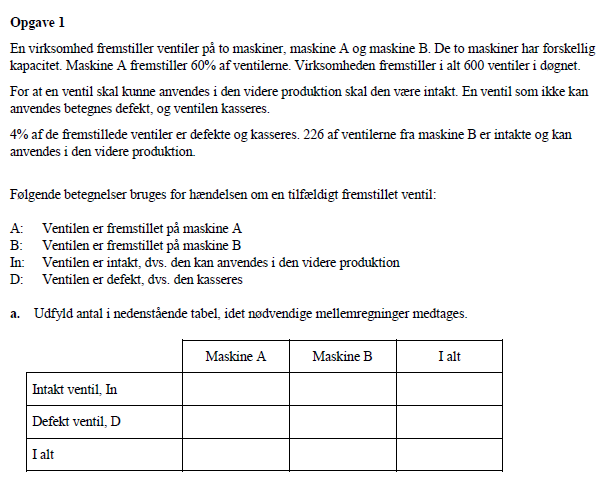

clc; clear;

n1 = "A";
n2 = "B";

n = 600;
n_intakt = n*0.96

n_intakt = 576

n_defekt = n-n_intakt

n_defekt = 24


nA = 0.6*n

nA = 360

nB = 0.4*n

nB = 240


inB = 226

inB = 226

inA = n_intakt-inB

inA = 350


dA = nA - inA

dA = 10

dB = n_defekt - dA

dB = 14

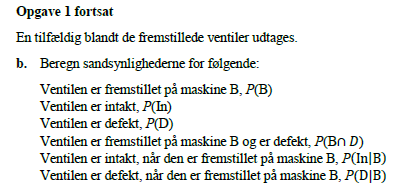

P_B = nB/n

P_B = 0.4000

P_in = (inB + inA)/n

P_in = 0.9600

P_D = (dA+dB)/n

P_D = 0.0400

P_BogD = dB/n

P_BogD = 0.0233

P_InogB = inB/nB

P_InogB = 0.9417

P_DogB = dB/nB

P_DogB = 0.0583

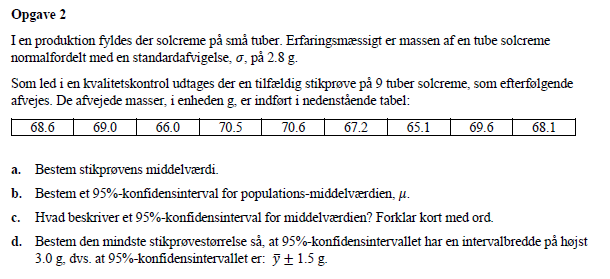

clc; clear;

std = 2.8; % gram

data = importdata("Data_M4STI1_2022E.xlsx");
stik = data.data(1:9,1)

stik =    68.6000
   69.0000
   66.0000
   70.5000
   70.6000
   67.2000
   65.1000
   69.6000
   68.1000



% a)
mdl = mean(stik)

mdl = 68.3000

Da populations-standardafvigelsen er kendt, vides det pr. den
centrale grænseværdi sætning at stikprøven er standard normalfordelt
Først regnes stikprøvemiddelværdien


$$\bar{y}=\frac{\Sigma \,y_{i}}{n}$$

Z værdien skal findes, vha. følgende formel


$$\frac{z_{\alpha }}{2}=\mathrm{norminv}\,\frac{\alpha }{2}$$

Dernæst regnes 95% konfidensintervallets værdier


$$\mathrm{Upper}=\bar{y}+\frac{\frac{z_{\alpha }}{2}\,\sigma }{\sqrt{n}}$$

$$\mathrm{Lower}=\bar{y}-\frac{\frac{z_{\alpha }}{2}\,\sigma }{\sqrt{n}}$$

    Interval    Værdier    Test type    Testværdier     Værdi     Deskriptorer
    ________    _______    _________    ___________    _______    ____________

    "Nedre"     66.471     "Z nedre"       -1.96       "y_bar"        68.3    
    "Øvre"      70.129     " Z øvre"        1.96       "sigma"         2.8    



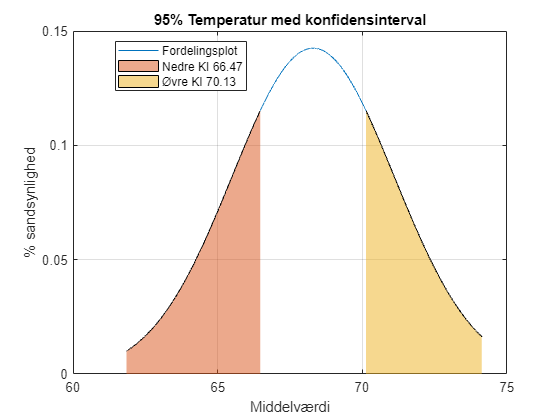


% b)
OP = KonfidensIntervalNormal(stik,95,std,mdl);


%c)
z_alpha_2 = OP.test_alpha(2)

z_alpha_2 = 1.9600

y_bar = 1.5

y_bar = 1.5000


n = (z_alpha_2*std/y_bar)^2

n = 13.3853


% Der rundes op til 14



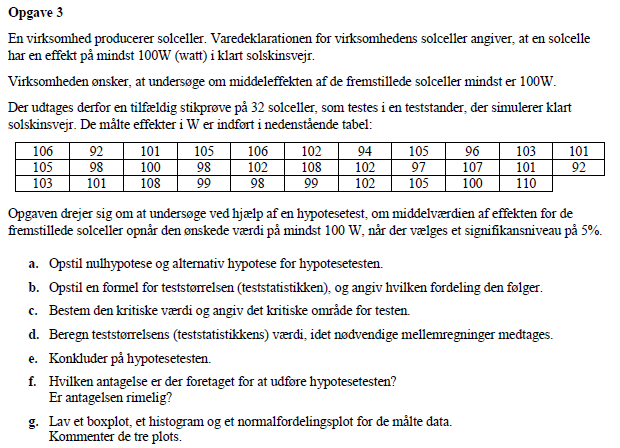

clc; clear;

data = importdata("Data_M4STI1_2022E.xlsx");
stik = data.data(:,4)

stik =    106
    92
   101
   105
   106
   102
    94
   105
    96
   103


Stikprøvemiddelværdiens formel


$$\bar{y}=\frac{\Sigma \,y_{i}}{n}$$

-----------------------------------------------------------------
Stikprøvevariansens formel


$$s=\frac{n\,\left(\Sigma \left({y_{i}}^{2}\right)-{\Sigma \left(y_{i}\right)}^{2}\right)}{n\,\left(n-1\right)}$$

-----------------------------------------------------------------
Stikprøvestandardafvigelsens formel


$$s=\sqrt{\frac{n\,\left(\Sigma \left({y_{i}}^{2}\right)-{\Sigma \left(y_{i}\right)}^{2}\right)}{n\,\left(n-1\right)}}$$

-----------------------------------------------------------------
t-værdiens formel


$$t_{\mathrm{df},\alpha }=\mathrm{tinv}\,\left(\alpha \,n-1\right)$$

-----------------------------------------------------------------
Teststørrelsens formel


$$t=\frac{\bar{y}-\mu_{0}}{s\,\sqrt{n}}$$

----------------------------------------------------------------------------------------------
    Datanavn    Middelværdi    Varians    Standardafv.    Datapunkter
      navn                                                           
    ________    ___________    _______    ____________    ___________

    {'stik'}      101.438      20.125        4.486            32     

    Frihedsgrader    Teststatistik      t0       p-værdi    h-værdi
    _____________    _____________    _______    _______    _______

         31              1.81         -1.6955    0.96021       0   



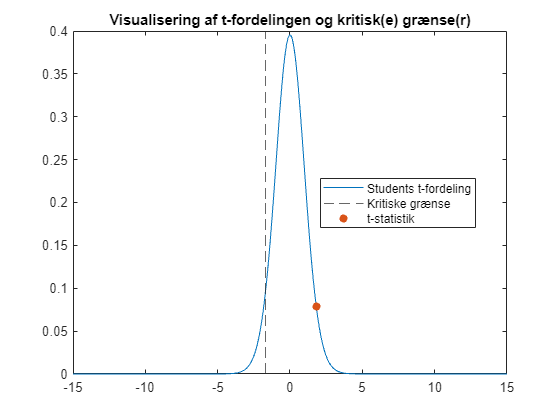

Da h = 0 forkastes nulhypotesen ikke
Ydermere ses det også at t-værdien 1.8127 ikke overstiger den kritiske grænse på -1.6955




% a)
% Nulhypotesen er: mu = 100W
% Alternativ er: mu < 100W
% Det vil sige en 1-sidet test

% b)
% Testen følger en t-fordeling, eftersom populationsvariansen ikke er kendt

% c)

StudentTestMiddel(stik,100,"left",95)

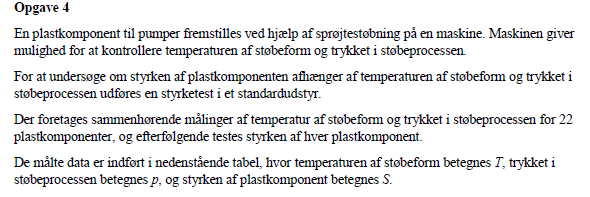

clc; clear;

data = importdata("Data_M4STI1_2022E.xlsx");
stik = data.data(1:22,7:9)

stik =     82    33   199
   103    34   247
    71    36   170
    43    13   124
    56    17   134
    62    27   173
    62    26   153
   119    22   254
    64    20   151
    52    13   169


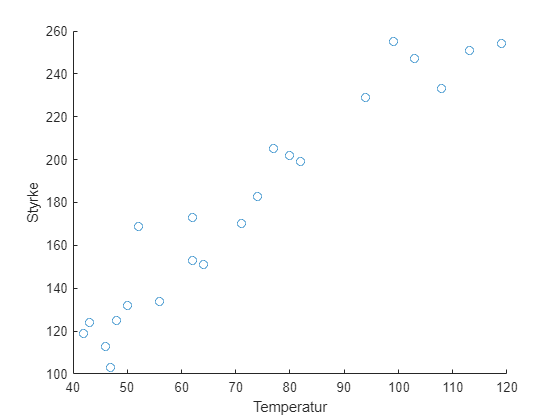


figure

title("Styrke som funktion af temperatur")
scatter(stik(:,1),stik(:,3))

xlabel("Temperatur")
ylabel("Styrke")

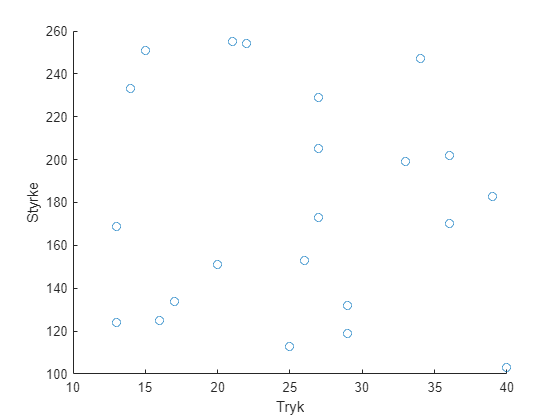



figure

title("Styrke som funktion af tryk")
scatter(stik(:,2),stik(:,3))

xlabel("Tryk")
ylabel("Styrke")

temp = stik(:,1);
tryk = stik(:,2);
styrke = stik(:,3);
mdl = fitlm([temp,tryk],styrke,'y ~ x1+x2+x1:x2')

mdl = Linear regression model:
    y ~ 1 + x1*x2

Estimated Coefficients:
                   Estimate      SE        tStat      pValue  
                   ________    _______    _______    _________

    (Intercept)      95.338     25.955     3.6732    0.0017394
    x1               1.1594    0.34721     3.3393    0.0036505
    x2              -2.7413     1.0874    -2.5211      0.02135
    x1:x2          0.037575    0.01486     2.5286     0.021017


Number of observations: 22, Error degrees of freedom: 18
Root Mean Squared Error: 12.8
R-squared: 0.945,  Adjusted R-Squared: 0.936
F-statistic vs. constant model: 103, p-value = 1.55e-11

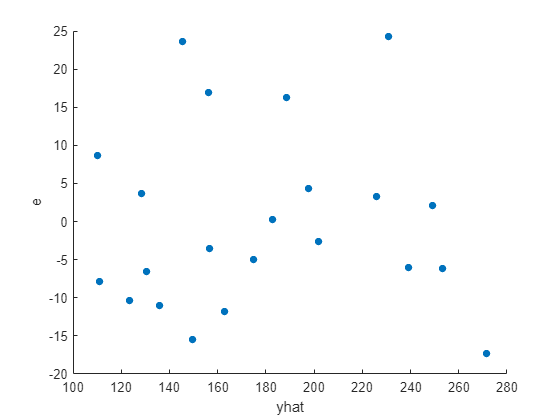

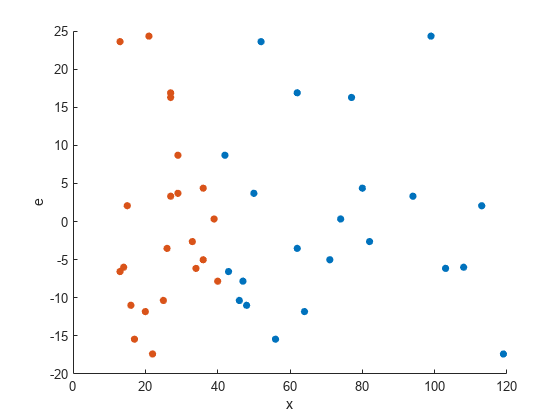

ans = 22×9 table
        x          y       lev         rst       levrage    outlier     yhat           yci            resid 
    __________    ___    ________    ________    _______    _______    ______    ________________    _______

     82     33    199     0.11515    -0.21209       0          0       201.63    192.49    210.76    -2.6261
    103     34    247     0.38355    -0.59984       1          0       253.14    236.48    269.81    -6.1428
     71     36    170     0.11802    -0.40688       0          0       175.01    165.77    184.26    -5.0121
     43     13    124     0.29958    -0.60103       1          0       130.56    115.83    145.29    -6.5605
     56     17    134 


STAT.Residual(mdl,stik).data